# **Práctica 4: filtros digitales IIR  **

clear;

## 1. Diseño de filtros IIR

load("PDS_P4_3A_LE2_G4.mat")

a) b) c) d) Se crean 4 filtros con fdatool y se cargan:

load("coef_b.mat")
load("coef_c_I.mat")
load("coef_c_II.mat")
load("coef_e.mat")

2. Análisis de filtros

2.1. Módulo y fase

a) Respuesta en Magnitud (dB vs Hz)

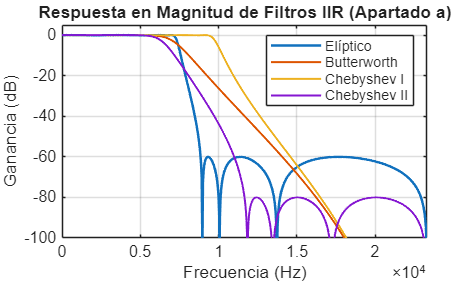

% Obtenemos la respuesta en frecuencia de los cuatro filtros diseñados
N_puntos = 50000; % Usamos N_puntos (50 000) y la frecuencia de muestreo Fs

[Hb, f_vec] = freqz(Num_b, Den_b, N_puntos, Fs);      % Butterworth
[HcI, ~]    = freqz(Num_c_I, Den_c_I, N_puntos, Fs);  % Chebyshev I
[HcII, ~]   = freqz(Num_CII, Den_CII, N_puntos, Fs);  % Chebyshev II
[He, ~]     = freqz(Num_e, Den_e, N_puntos, Fs);      % Elíptico

% Representación de la Magnitud en dB
figure;
plot(f_vec, 20*log10(abs(He)), 'LineWidth', 1.5); hold on;
plot(f_vec, 20*log10(abs(Hb)), 'LineWidth', 1.2);
plot(f_vec, 20*log10(abs(HcI)), 'LineWidth', 1.2);
plot(f_vec, 20*log10(abs(HcII)), 'LineWidth', 1.2);
grid on;
title('Respuesta en Magnitud de Filtros IIR (Apartado a)');
xlabel('Frecuencia (Hz)');
ylabel('Ganancia (dB)');
legend('Elíptico', 'Butterworth', 'Chebyshev I', 'Chebyshev II');
axis([0 Fs/2 -100 5]); % Ajuste de ejes para ver el detalle del rizado y caída

b) Respuesta en Fase (Radianes vs Hz)

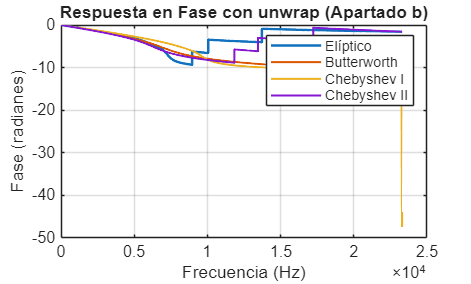

% Se utiliza la función unwrap para eliminar los saltos de fase de ±pi
% Aprovechamos los vectores calculados en la celda anterior

figure;
plot(f_vec, unwrap(angle(He)), 'LineWidth', 1.5); hold on;
plot(f_vec, unwrap(angle(Hb)), 'LineWidth', 1.2);
plot(f_vec, unwrap(angle(HcI)), 'LineWidth', 1.2);
plot(f_vec, unwrap(angle(HcII)), 'LineWidth', 1.2);
grid on;
title('Respuesta en Fase con unwrap (Apartado b)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (radianes)');
legend('Elíptico', 'Butterworth', 'Chebyshev I', 'Chebyshev II');

2.2. Polos y ceros

a) Representación del diagrama de polos y ceros

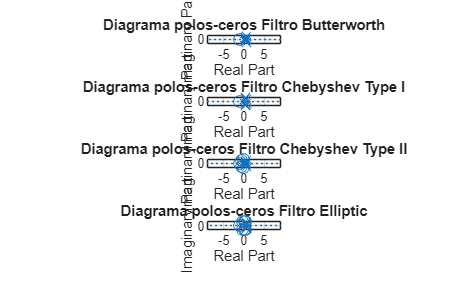

B = {Num_b, Num_c_I, Num_CII, Num_e};   % numeradores
A = {Den_b, Den_c_I, Den_CII, Den_e};   % denominadores
nombres = {"Butterworth", "Chebyshev Type I", "Chebyshev Type II", "Elliptic"};

N = 4; % Número de filtros que tenemos

figure;
for k = 1:N
    subplot(N,1,k);
    z = roots(B{k});
    p = roots(A{k});
    zplane(z,p);
    title(sprintf('Diagrama polos-ceros Filtro %s',nombres{k}));
    grid on;
end

b) ¿Son estables los filtros? ¿Por qué?

for k = 1:N
    p = roots(A{k});

    if all(abs(p) < 1)
        disp((sprintf('El filtro %s es estable', nombres{k})));
    else
        disp((sprintf('El filtro %s NO es estable', nombres{k})));
    end   
end

El filtro Butterworth es estable
El filtro Chebyshev Type I es estable
El filtro Chebyshev Type II es estable
El filtro Elliptic es estable


c) Justificación de por qué son paso bajo

% Partimos leyendo desde un ángulo (frecuencia) cero en los diagramas mostrados anteriormente y, 
% según vaya encontrado polos (lo primero que encuentro) ello hace que la amplitud de mi filtro tienda a infinito (no a cero)
%  y que por lo tanto, aumentan mi banda de paso. En el momento en que, recorriendo la circunferencia y aumentando la frecuencia,
%  encuentro mi primer cero, justo en ese instante se produce el cambio entre la banda de paso y la banda eliminada (manteniéndonos 
% en dicha banda eliminada hasta llegar a pi).

% Destacar que la representación es simétrica con respecto al eje real (x) por el hecho de trabajar con filtros reales, donde los polos 
% y los ceros aparecen a pares como complejos conjugados. Es por este hecho que solo estudiamos de 0 a pi, porque lo que hay entre pi y 2pi 
% es idéntico y no aporta información novedosa para el caso concreto. Además, pi es nuestra última frecuencia digital (la frecuencia de Nyquist).

d) Justificación matemática de los máximos de oscilación (Filtro Elíptico)

raices = roots(Den_e);
w = angle(raices);
w_pos = w(w >= 0);
w_norm = w_pos / pi;

f_analog = w_norm * (Fs/2); % Frecuencias analógicas en Hz

disp(f_analog);

   1.0e+03 *

    7.2747
    6.5773
    4.5025
         0



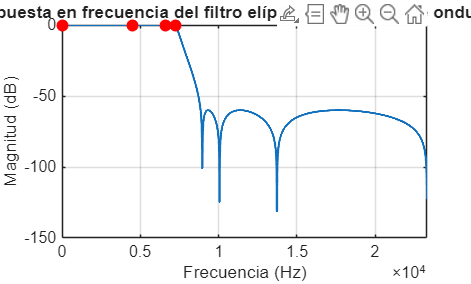

Npoints = 8192;   % más puntos para mayor precisión

[H, W] = freqz(Num_e, Den_e, Npoints, Fs);

figure;
plot(W, 20*log10(abs(H)), 'LineWidth', 1.4); 
hold on;

% Marcadores de los máximos (frecuencias analógicas obtenidas)
stem(f_analog, ...
     max(20*log10(abs(H))) * ones(size(f_analog)), ...
     'r', 'filled', 'LineWidth', 1.2);

title('Respuesta en frecuencia del filtro elíptico y máximos de ondulación');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (dB)');
grid on;
xlim([0 Fs/2]);   % solo banda positiva

e) Frecuencias eliminadas en el Filtro Elíptico    

% Las frecuencias eliminadas corresponden a los ceros situados sobre el círculo unidad.

% 1. Calculamos las raíces del numerador (ceros) del filtro elíptico
ceros_e = roots(Num_e);

% 2. Obtenemos el ángulo (fase) de los ceros en radianes
angulos_ceros = angle(ceros_e);

% 3. Convertimos los ángulos a frecuencias en Hz: f = (ang * Fs) / (2*pi)
% Filtramos solo los ángulos positivos para no repetir frecuencias simétricas
f_eliminadas = sort(angulos_ceros(angulos_ceros > 0)) * Fs / (2*pi);

% 4. Mostramos los resultados
fprintf('Las frecuencias eliminadas (ceros de transmisión) son:\n');

Las frecuencias eliminadas (ceros de transmisión) son:


for i = 1:length(f_eliminadas)
    fprintf('Frecuencia %d: %.2f Hz\n', i, f_eliminadas(i));
end

Frecuencia 1: 8957.86 Hz
Frecuencia 2: 10057.60 Hz
Frecuencia 3: 13721.17 Hz
Frecuencia 4: 23300.00 Hz


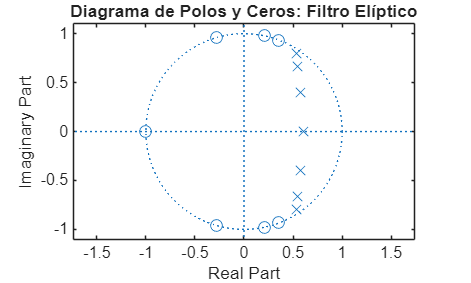


% Visualización para comprobación
figure;
zplane(Num_e, Den_e);
title('Diagrama de Polos y Ceros: Filtro Elíptico');

2.3. Estabilidad

a) Modificar el filtro elíptico multiplicando sus polos por un factor de 0.95.

% Obtención polos y ceros
poles = roots(Den_e);
zeros = roots(Num_e);

poles_095 = 0.95 * poles;

% Reconstrucción del denominador en función de los nuevos polos
Den_095 = poly(poles_095);
Num_095 = Num_e

Num_095 =     0.0073    0.0030    0.0152    0.0122    0.0122    0.0152    0.0030    0.0073




% Para obtener un filtro más estable, se ha modificado el filtro elíptico original multiplicando la localización de sus polos por un factor 0.95.
% Al acercar los polos al origen, el módulo de todos ellos disminuye y se mejora la estabilidad del filtro.

b) Coeficientes del filtro modificado (Factor 0.95)

% Mostrar resultados por pantalla
disp('-----------------------------------------------');

-----------------------------------------------


disp('Coeficientes del filtro modificado (polos × 0.95)');

Coeficientes del filtro modificado (polos × 0.95)


disp('Numerador (b):');

Numerador (b):


disp(Num_095);

    0.0073    0.0030    0.0152    0.0122    0.0122    0.0152    0.0030    0.0073




disp('Denominador (a):');

Denominador (a):


disp(Den_095);

    1.0000   -3.7155    7.0342   -8.2342    6.3696   -3.2217    0.9866   -0.1414



disp('-----------------------------------------------');

-----------------------------------------------


c) Modificar el filtro elíptico multiplicando sus polos por un factor de 1,05.

% Los polos del origen → mayor selectividad → riesgo de inestabilidad.
poles_105 = 1.05 * poles;
Den_105 = poly(poles_105);
Num_105 = Num_e;

d) Coeficientes del filtro modificado (Factor 1.05)

% Mostrar resultados
disp('-----------------------------------------------');

-----------------------------------------------


disp('Coeficientes del filtro modificado (polos × 1.05)');

Coeficientes del filtro modificado (polos × 1.05)


disp('Numerador (b):');

Numerador (b):


disp(Num_105);

    0.0073    0.0030    0.0152    0.0122    0.0122    0.0152    0.0030    0.0073




disp('Denominador (a):');

Denominador (a):


disp(Den_105);

    1.0000   -4.1066    8.5930  -11.1179    9.5054   -5.3139    1.7986   -0.2850



disp('-----------------------------------------------');

-----------------------------------------------


e) Calcule la respuesta impulsional del filtro original y los dos filtros nuevos

% Cálculo de las respuestas impulsionales
[h_orig, t_orig] = impz(Num_e,   Den_e);
[h_095,  t_095 ] = impz(Num_095, Den_095);
[h_105,  t_105 ] = impz(Num_105, Den_105);


% Mostrar resultado por texto
disp('-----------------------------------------------');

-----------------------------------------------


disp('Respuesta impulsional calculada para los tres filtros.');

Respuesta impulsional calculada para los tres filtros.


disp('Vectores h_orig, h_095, h_105 almacenan las respuestas.');

Vectores h_orig, h_095, h_105 almacenan las respuestas.


disp('-----------------------------------------------');

-----------------------------------------------


f) Efectos en la respuesta en frecuencia

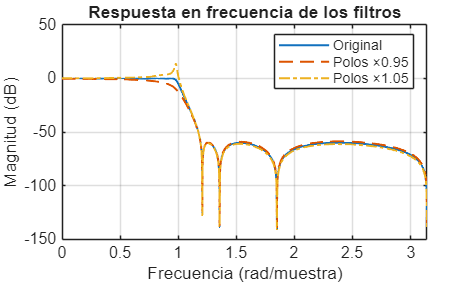

%Respuesta en frecuencia de los 3 filtros

Npts = 50000; %por no sobrecargar el ordenador

% Filtro original
[H_orig, w] = freqz(Num_e,   Den_e,   Npts);
% Filtro polos ×0.95
H_095 = freqz(Num_095, Den_095, Npts);
% Filtro polos ×1.05
H_105 = freqz(Num_105, Den_105, Npts);

figure;
plot(w, 20*log10(abs(H_orig)), 'LineWidth', 1.2); hold on;
plot(w, 20*log10(abs(H_095)),  '--', 'LineWidth', 1.2);
plot(w, 20*log10(abs(H_105)),  '-.', 'LineWidth', 1.2);

title('Respuesta en frecuencia de los filtros');
xlabel('Frecuencia (rad/muestra)');
ylabel('Magnitud (dB)');
legend('Original', 'Polos ×0.95', 'Polos ×1.05');
grid on;

g) Efectos en el diagrama de polos y ceros

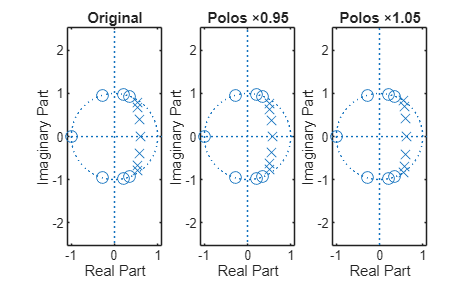

% Diagramas de polos y ceros

figure;

subplot(1,3,1);
zplane(Num_e, Den_e);
title('Original');

subplot(1,3,2);
zplane(Num_095, Den_095);
title('Polos ×0.95');

subplot(1,3,3);
zplane(Num_105, Den_105);
title('Polos ×1.05');

h) Efectos en la respuesta impulsional

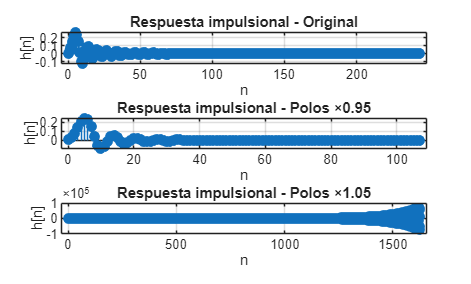

% Respuesta impulsional de los 3 filtros

[h_orig, t_orig] = impz(Num_e,   Den_e);
[h_095,  t_095 ] = impz(Num_095, Den_095);
[h_105,  t_105 ] = impz(Num_105, Den_105);

figure;

subplot(3,1,1);
stem(t_orig, h_orig, 'filled');
title('Respuesta impulsional - Original');
xlabel('n'); ylabel('h[n]'); grid on;

subplot(3,1,2);
stem(t_095, h_095, 'filled');
title('Respuesta impulsional - Polos ×0.95');
xlabel('n'); ylabel('h[n]'); grid on;

subplot(3,1,3);
stem(t_105, h_105, 'filled');
title('Respuesta impulsional - Polos ×1.05');
xlabel('n'); ylabel('h[n]'); grid on;